# Sensitivity of a flux balance analysis solution with respect to input data

## Author(s): Ronan M.T. Fleming, Leiden University

## Reviewer(s): 

## INTRODUCTION

Consider an FBA problem


$$
\begin{array}{ll}
\textrm{max} & c^{T}v\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u
\end{array}
\end{equation}$$


The local sensitivity of the optimal objective value $\mathcal{L}^{\star} = c^{T}v^{\star}$  with respect to a changes in the input data $\left\lbrace b,l,u\right\rbrace$ is given by

 
$$\frac{\partial\mathcal{L}^{\star}}{\partial b} = y^{\star} \\
\frac{\partial\mathcal{\mathcal{L}^{\star}}}{\partial l} = -w_{l}^{\star} \\
\frac{\partial\mathcal{\mathcal{L}^{\star}}}{\partial u} = w_{u}^{\star}
$$


where $y^{\star}$ is a vector of shadow prices and $w = w_{l}-w_{u}$ is a vector of reduced costs. That is, a shadow price is the partial derivative of the optimal value of the objective function with respect to $b_i$.  It indicates how much net production, or net consumption, of each metabolite increases (positive), or decreases (negative), the optimal value of the objective. The reduced costs, $-w_l$ and $w_{u\;}$are the partial derivative of the optimal value of the objective function with respect to the lower and upper bounds on a reaction, respectively. They indicate how much relaxation, or tightening, of each bound increases, or decreases, the optimal objective, respectively. In the COBRA Toolbox, shadow prices and reduced costs are calculated by `optimizeCbModel`. When using the function

`FBAsolution = optimizeCbModel(model,'max');`

the shadow prices and reduced costs are given by `FBAsolution.y `and` FBAsolution.w`, respectively. 

For a more complete theoretical description, see: cobratoolbox/tutorials/intro_sensitivityAnalysis.pdf

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most direct way to load a model into The COBRA Toolbox is to use the `readCbModel` function. For example, to load a model from a MAT-file, you can simply use the filename (with or without file extension). 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

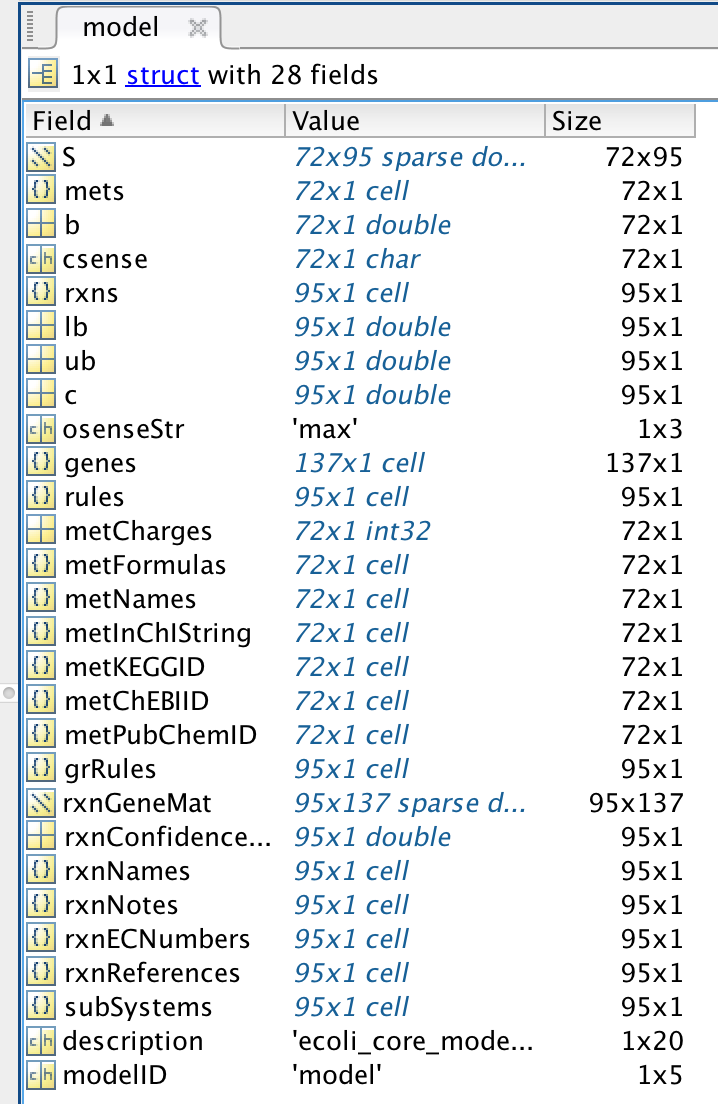

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Sensitivity Analysis

#### In the E. coli core model, when maximising ATP production, what is the shadow price of cytosolic protons? 

#### Hint: `FBAsolution.y`

model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-1,'l');
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeObjective(model,'ATPM');
printConstraints(model,-1000,1000)

MinConstraints:
EX_glc(e)	-1
maxConstraints:



FBAsolution_maxATP = optimizeCbModel(model,'max');

Check the optimal value of the objective

FBAsolution_maxATP.f

ans = 17.5000

The shadow price of cytosolic protons (h[c]) is -0.25. 

ind=strcmp(model.mets,'h[c]');
FBAsolution_maxATP.y(ind)

ans = -0.2500

printFluxVector(model, FBAsolution_maxATP.v, 1)

ACONTa              	           2
ACONTb              	           2
AKGDH               	           2
ATPM                	        17.5
ATPS4r              	        13.5
CO2t                	          -6
CS                  	           2
CYTBD               	          12
ENO                 	           2
EX_co2(e)           	           6
EX_glc(e)           	          -1
EX_h2o(e)           	           6
EX_o2(e)            	          -6
FBA                 	           1
FUM                 	           2
GAPD                	           2
GLCpts              	           1
H2Ot                	          -6
ICDHyr              	           2
MDH                 	           2
NADH16              	          10
NADTRHD             	           2
O2t                 	           6
PDH                 	           2
PFK                 	           1
PGI                 	           1
PGK                 	          -2
PGM                 	          -2
PYK                 	           1
SUCDi         

Remove 4 units of cytoplasmic protons from the system and calculate the difference in the value of the optimal objective:

model.b(ind) = 4;
FBAsolution_maxATP_forceH = optimizeCbModel(model,'max');
FBAsolution_maxATP_forceH.f - FBAsolution_maxATP.f

ans = 1

#### What is your biochemical interpretation of this change in objective in the current context?

#### Hint: printFluxVector, drawFlux

This is a unique solution (see Example 3). 

dv = FBAsolution_maxATP_forceH.v-FBAsolution_maxATP.v;
dv(abs(dv)<1e-5)=0;
printFluxVector(model, dv, 1)

ATPM                	           1
ATPS4r              	           1
EX_h(e)             	          -4


The flux map for optimal ATP production is shown below.  

drawFlux(map, model, FBAsolution_maxATP.v, options);

Unrecognized function or variable 'map'.

ATP production is constrained by cytoplasmic proton balancing.  Cytoplasmic protons are produced by various metabolic reactions and also enter into the cell, from the extracellular compartment, via the ATP synthase reaction (ATPS4r).  At steady-state, an equal number of protons must be pumped out of the cytoplasm by the electron transport chain reactions or by excreting metabolites with symporters. Setting model.b(i) = 4, where i corresponds to cytoplasmic protons, h[c], removes 4 extra units of cytoplasmic protons from the system allowing 4 extra extracellular protons to enter the system that then enter the cell via the ATP synthase reaction, generating one extra unit of ATP. This increases the maximum rate of ATP synthesis by one unit, thereby increasing the ATP yield from glucose by 1 mol ATP/mol glucose. 

#### In the E. coli core model, when maximising ATP production, what is the reduced cost of glucose exchange? 

#### Hint: FBAsolution.rcost

rcost = FBAsolution_maxATP.rcost;
rcost(abs(rcost)<1e-4)=0;
flux=FBAsolution_maxATP.v;
printFluxVector(model, [model.lb,flux,model.ub,rcost], 1)
ind=strcmp(model.rxns,'EX_glc(e)');
FBAsolution_maxATP.rcost(ind)
model = modelOri;
model = changeRxnBounds(model,'EX_glc(e)',-2,'l'); %note the change in the lower bound from -1 to -2
model = changeRxnBounds(model,'EX_o2(e)',-1000,'l');
model = changeRxnBounds(model,'ATPM',0,'l');
model = changeObjective(model,'ATPM');
FBAsolution_maxATP_moreGlc = optimizeCbModel(model,'max');

By changing the lower bound on glucose exhange from -1 to -2, we see that the value of the objective increases by 17.5, which is equal to the reduced cost of glucose obtained from FBAsolution_maxATP.rcost:

FBAsolution_maxATP_moreGlc.f - FBAsolution_maxATP.f

Display the change in the flux vector:

dv = FBAsolution_maxATP_moreGlc.v-FBAsolution_maxATP.v;
dv(abs(dv)<1e-4)=0;
printFluxVector(model, dv, 1)

## TROUBLESHOOTING

Note that, if an optimization problem is reformulated from a maximisation to a minimisation problem, then the signs of each of the dual variables is reversed.

## TIMING

*1 hr.*

## ANTICIPATED RESULTS

Understanding of how an optimal objective will change in response to changing the input data.

## *Acknowledgments*

Part of this tutorial was originally written by Jeff Orth and Ines Thiele for the publication "What is flux balance analysis?"

## REFERENCES

1.    Orth. J., Thiele, I., Palsson, B.O., What is flux balance analysis? Nat Biotechnol. Mar; 28(3): 245–248 (2010).

2. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).